Laptop Data Units (SwingDAQ)

- Acceleration: m/s^2

- Orientation: Degrees

- Angular Velocity: degrees/s

- Forces: lb

Phone Data Units

- Acceleration: m/s^2

- Orientation: Degrees

- Angular Velocity: rad/s

Load swingDAQ data

% Load Data
load swingdata.mat 

% If you want to write to excel, uncomment
% writetable(acquiredData, "swingdata.xlsx");

% Remove possible spikes from LC1 to LC6
LC1 = removespikes(acquiredData.LC1);
LC2 = removespikes(acquiredData.LC2);
LC3 = removespikes(acquiredData.LC3);
LC4 = removespikes(acquiredData.LC4);
LC5 = removespikes(acquiredData.LC5);
LC6 = removespikes(acquiredData.LC6);

% Angular Velocity from Laptop is in degrees/s
% Change to rad/s
acquiredData.OmegaX = acquiredData.OmegaX * (pi/180);
acquiredData.OmegaY = acquiredData.OmegaY * (pi/180);
acquiredData.OmegaZ = acquiredData.OmegaZ * (pi/180);

% Define the lenghts and heights of swingset (in meters)
w = 1.651 % 65 inches

w = 1.6510

H = 1.829 % 72 inches

H = 1.8290

l = 2.006 % 79 inches

l = 2.0060

h = 1.524 % 60 inches

h = 1.5240

s = 0.432 % 17 inches

s = 0.4320

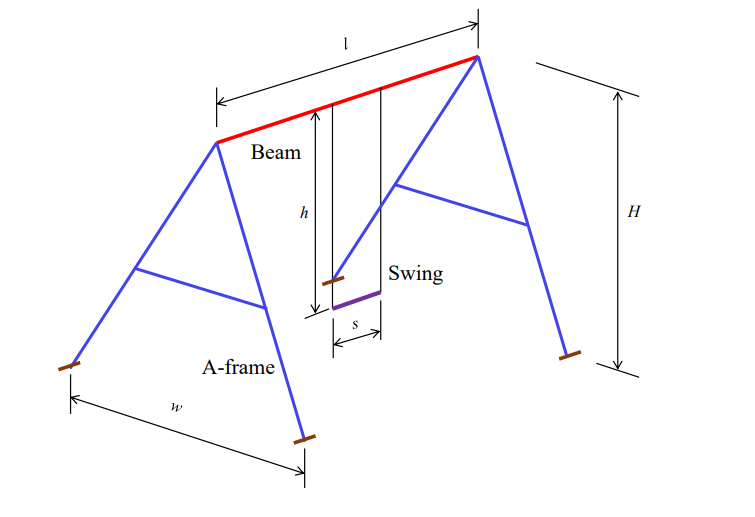

Load Phone Data


% Load Data
load phonedata.mat

Acceleration = renamevars(Acceleration, ["X","Y","Z"],...
["AccelX","AccelY","AccelZ"]);
AngularVelocity = renamevars(AngularVelocity, ["X","Y","Z"],...
["OmegaY","OmegaX","OmegaZ"]);
Orientation = renamevars(Orientation, ["X","Y","Z"],...
["OrientX","OrientY","OrientZ"]); % Note the switch in order
% because of naming convention in
% MATLAB Mobile/iphone

phoneData = synchronize(Acceleration, AngularVelocity, Orientation, ...
'union', 'linear'); % Merge the three timetables into one
% If want to write to Excel, uncomment
% writetimetable(phoneData,"phoneData.xlsx");

% find index of each peak
%[~, idx1] = max(acquiredData.OrientY);
%[~, idx2] = max(phoneData.OrientY);
%toffset = acquiredData.Time(idx1) - phoneData.Time(idx2); % offset between swing and phone data obtained
% by comparing peaks in OrientY

%toffset = -17.677
%disp(toffset);
%t_phone = second(phoneData.Timestamp,"secondofday");
%t_phone = t_phone - t_phone(1)-toffset;

% Change timestamps from phone data to seconds
% We do this so it matches the laptop data better
phoneData.TimeOnly = timeofday(phoneData.Timestamp);
phoneData.TimeOnly.Format = 'hh:mm:ss.SSS';
initial_time = phoneData.TimeOnly(1);
phoneData.Time = phoneData.TimeOnly - initial_time;
phoneData = removevars(phoneData, 'TimeOnly');
time_seconds = seconds(phoneData.Time);
phoneData.Time = time_seconds;

clear Acceleration AngularVelocity Orientation

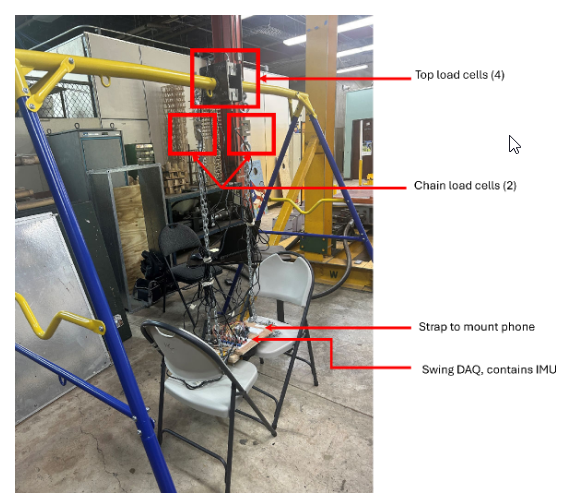

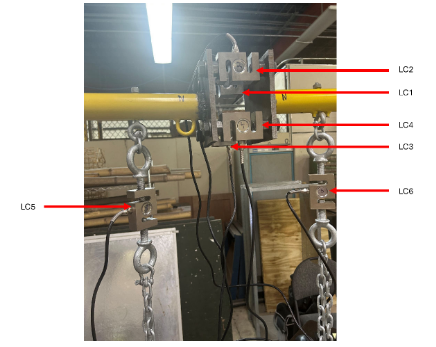

Purposes:

- IMU - Measure acceleration and angular velocity. Estimate orientation.

- LC5 & LC6 - Measure Chain Tension.

- LC1 through LC4 - Measure Beam Bending Moment.

What we need to measure from our datasets:

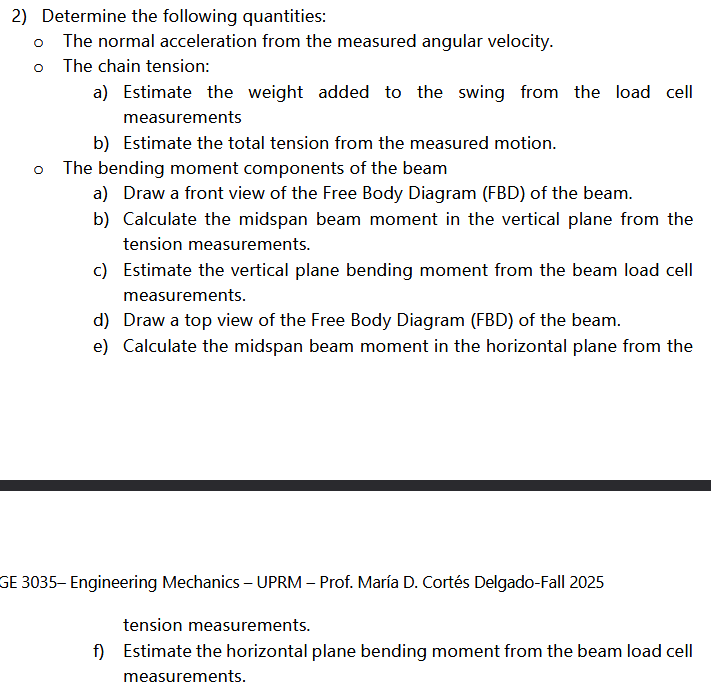

Calculate time offset between laptop and phone data

time_laptop = acquiredData.Time;
time_phone = phoneData.Time;
orient_y_laptop = acquiredData.OrientY;
orient_y_phone = phoneData.OrientY;

disp("Orientation Graphs without time offset applied.")

Orientation Graphs without time offset applied.


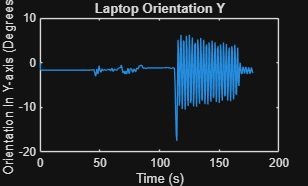

plot(time_laptop, orient_y_laptop);
title("Laptop Orientation Y");
ylabel("Orientation In Y-axis (Degrees)");
xlabel("Time (s)");

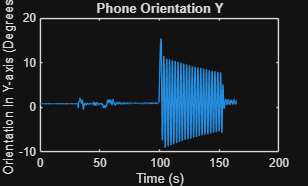

clear plot

plot(time_phone, orient_y_phone);
title("Phone Orientation Y");
ylabel("Orientation In Y-axis (Degrees)");
xlabel("Time (s)");

clear plot

% Movement in Y Orientation of Laptop Data starts at X=114.502
% Movement in Y Orientation of Phone Data starts at X=101.171
% We can use this to calculate the offset time 
toffset = 114.502 - 101.171;
disp("Time Offset that needs to be applied to phone data and graphs:")

Time Offset that needs to be applied to phone data and graphs:


disp(toffset);

   13.3310




phoneData.Time = phoneData.Time + toffset;
time_phone = phoneData.Time; % Update variable to include time with offsets

disp("Orientation Graphs with time offset applied.")

Orientation Graphs with time offset applied.


plot(time_laptop, orient_y_laptop);
title("Laptop Orientation Y");
ylabel("Orientation In Y-axis (Degrees)");
xlabel("Time (s)");

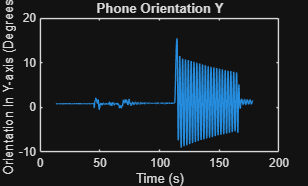

clear plot

plot(time_phone, orient_y_phone);
title("Phone Orientation Y");
ylabel("Orientation In Y-axis (Degrees)");
xlabel("Time (s)");

clear plot

Calculate Normal Acceleration

% Calculate with data from both laptop and phone 
% Radius is equal to height of chains = 60 inches or 1.524 meters
r = h; % Set radius equal to height of chains

% Calculate average normal acceleration with laptop data
mag_omega_laptop = sqrt((acquiredData.OmegaX.^2) + (acquiredData.OmegaY.^2) + (acquiredData.OmegaZ.^2));
a_normal_laptop = (mag_omega_laptop.^2) * r;
avg_a_normal_laptop = mean(a_normal_laptop);
disp("Normal Acceleration using Laptop Data")

Normal Acceleration using Laptop Data


disp(avg_a_normal_laptop + " m/s^2");

0.071552 m/s^2



% Calculate average normal acceleration with phone data
mag_omega_phone = sqrt(phoneData.OmegaX.^2 + phoneData.OmegaY.^2 + phoneData.OmegaZ.^2);
a_normal_phone = (mag_omega_phone.^2) * r;
avg_a_normal_phone = mean(a_normal_phone);
disp("Normal Acceleration using Phone Data");

Normal Acceleration using Phone Data


disp(avg_a_normal_phone + " m/s^2");

0.0746 m/s^2


clear plot 

Graph Angular Velocity in Y from Laptop and Phone Data

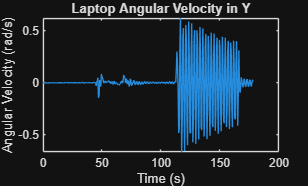

time = acquiredData.Time;
ang_vel_laptop_y = acquiredData.OmegaY;

plot(time, ang_vel_laptop_y);
title("Laptop Angular Velocity in Y");
xlabel("Time (s)");
ylabel("Angular Velocity (rad/s)");

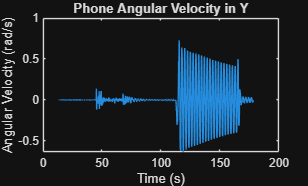

clear plot 

time = phoneData.Time;
ang_vel_phone_y = phoneData.OmegaY;
plot(time, ang_vel_phone_y);
title("Phone Angular Velocity in Y");
xlabel("Time (s)");
ylabel("Angular Velocity (rad/s)");

clear plot

Calculate Weight and Total Tension

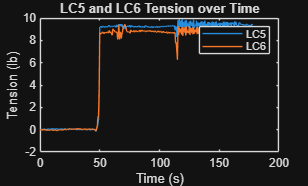

% Graph the force measurements from LC5 and LC6 for reference
% LC5 and LC6 are in between their chain connecting swing and beam
time = acquiredData.Time;
lc5_col = acquiredData.LC5;
plot(time,lc5_col);
hold on

lc6_col = acquiredData.LC6;
title("LC5 and LC6 Tension over Time");
xlabel('Time (s)');
ylabel('Tension (lb)');
plot(time,lc6_col);
legend("LC5", "LC6")
hold off

clear plot

% Between both chains:
% While swing is still on the platform, F = ma -> F ~ -0.149 lb
% After swing is suspended on the air, F = ma -> F ~ 8.95 lb
platform_f = -0.149; % We could say it's 0 too
suspended_f = 8.95;
delta_f = suspended_f - platform_f;
disp("Tension when swing is on the platform: " + platform_f + " lb");

Tension when swing is on the platform: -0.149 lb


disp("Tension when swing is suspended mid-air by chains: " + suspended_f + " lb");

Tension when swing is suspended mid-air by chains: 8.95 lb


disp(" ");


% This difference corresponds to the force that the chains must supply to lift 
% the swing off the platform, which is effectively the weight of the swing.
% We only account for static calculations. mass = DeltaF / g
weight_mass = delta_f / 32.17;
disp("Mass of the swing");

Mass of the swing


disp(weight_mass + " slugs");

0.28284 slugs



% We can calculate the weight of the swing now
% W = mg
weight_swing = weight_mass * 32.17;
disp("Weight of the swing");

Weight of the swing


disp(weight_swing + " lb");

9.099 lb


disp(" ");

Calculate Centrifugal Acceleration

% Height of swing chains = 60 inches or 1.524 meters
ac = acquiredData.OmegaY.^2 * h;
avg_ac = mean(ac);

disp("Centrifugal Acceleration using Laptop Data");

Centrifugal Acceleration using Laptop Data


disp(avg_ac + " m/s^2");

0.062861 m/s^2
